This script is a part of the supplementary material for the following paper:

-  Jamshidi Idaji et al,  "Nonlinear Interaction Decomposition (NID): A Method for Separation of Cross-frequency Coupled Sources in Human Brain". doi: [https://doi.org/10.1101/680397](https://doi.org/10.1101/680397)

Corresponding Author: Vadim V. Nikulin (nikulin@cbs.mpg.de)

(C) Mina Jamshidi Idaji, Oct 2019, @ MPI CBS, Leipzig, Germany

jamshidi@cbs.mpg.de    .         minajamshidi91@gmail.com

[https://github.com/minajamshidi/NID](https://github.com/minajamshidi/NID)

* This code is based on the code used in:

Nikulin, V.V., Nolte, G., Curio, G., 2012. Cross-frequency decomposition: A novel technique for studying interactions between neuronal oscillations with different frequencies. Clinical Neurophysiology 123, 1353–1360. doi:10.1016/j.clinph.2011.12.004.

**Please cite the above papers (or a future peer-reviewed version) in case of any significant usage of this script  or the simulation pipeline.**

# **Supplementary Code (5)**

# Realistic EEG Simulations: A Comprehensive Tutorial

In this script, we go through our realistic EEG simulation pipeline of our paper.

**Please cite the above papers (or a future peer-reviewed version) in case of any significant usage of this script or the simulation pipeline.**

For this script, you will need the [METH toolbox](https://www.uke.de/english/departments-institutes/institutes/neurophysiology-and-pathophysiology/research/research-groups/index.html).  You can download the pipeline from our [GitHub](https://github.com/minajamshidi/NID). Please download the package and add its to your MATLAB's directory - we will use one of its function in this script.

 In the following we will go through the function `Produce_EEG_CFC` for simulation of realistic EEG with CFC coupled sources.

## Parameter Settings

First, add the path of METH toolbox:

%NID_dir = './NID_GitHub'; % you may add your own directory
%meth_dir = './meth'; % you may add your own directory
%addpath(genpath(meth_dir));
%addpath(genpath(NID_dir));

The parameter of the fuction `Produce_EEG_CFC` are:

PairsNum = 2; %number of the coupled pairs 
FrBase = 10; % base frequency in Hz.
% The CFC osillations will be at frequencies FrP*FrBase and FrQ*FrBase.
FrP = 1; % frequency ratio of the slow oscillation
FrQ = 2;  % frequency ratio of the fast oscillation
Fs = 500; % sampling frequency
SNR = 0.3162; % signal-to-noise ratio
PhaseLag_q = 0; % phase lag of the coupled oscilaltions
T_sec = 5*60; % length of the simulated signal in seconds
seed = 4443000; %random seed for reproducing the results
%seed = randperm(9999999,1); % you may generate new seeds 

Now we load the head model and set some more parameters:

rng(seed,'twister'); % for reproducing the results
load('sa_eeg.mat'); % the head 
source_analysis = sa; clear sa;

electrode_locs = source_analysis.locs_2D; % electrode locations
T = Fs * T_sec; %number of time samples in the signal
NoiseNum = 125;% number of pink noise sources
SourceNum = PairsNum * 2;

Note that in the function we put all the parameters in a structure and then unpack it in the next function.

Build the filters:

[butter_base_b, butter_base_a] = butter(2,[FrBase-1 FrBase+1]/(Fs/2));          
[butter_p_b, butter_p_a] = butter(2,[FrP*FrBase-1 FrP*FrBase+1]/(Fs/2));    
[butter_q_b, butter_q_a] = butter(2,[FrQ*FrBase-1 FrQ*FrBase+1]/(Fs/2));  

## Simulating the Dipoles

The next step is to simulate the dipoles and do the forward modelling to generate the mixing patterns of the sources. This is done in the function `mk_model_mni`, which we expand in the following code segments.

First: we generate the noise dipoles by making a grid of 5x5x5 and selecting a dipole from each cell randomely. With this we gaurantee that the noise dipoles are homogeneously distributed over the cortical mantle and are not located at a specific region.

% generate noise dipoles
N = ceil(nthroot(NoiseNum,3));
vc = source_analysis.cortex.vc;
vc_x = vc(:,1);
vc_y = vc(:,2);
vc_z = vc(:,3);
x_bins = linspace(min(vc_x)-0.1,  max(vc_x)+0.1, N+1);
y_bins = linspace(min(vc_y)-0.1,  max(vc_y)+0.1, N+1);
z_bins = linspace(min(vc_z)-0.1,  max(vc_z)+0.1, N+1);
n = 0;
dipole_pos_3d_noise = NaN(N^3,3);
for ix = 1:N
    for iy = 1:N
        for iz = 1:N
            n = n + 1;
            IND = vc_x>=x_bins(ix) & vc_x<x_bins(ix+1) & ...
                vc_y>=y_bins(iy) & vc_y<y_bins(iy+1) & ...
                vc_z>=z_bins(iz) & vc_z<z_bins(iz+1);
            if ~sum(IND)
                dipole_pos_3d_noise(n,:) = [];
                n = n - 1;
            else
                vc_ind = vc(IND,:);
                idx_vox = randi(sum(IND), 1);
                dipole_pos_3d_noise(n, :) = vc_ind(idx_vox,:);
            end
            
        end
    end
end
NoiseNum = size(dipole_pos_3d_noise, 1);

Second: we generate the dipole orientations. For this purpose, the orientaions (dipole_orient_3d) are produced by selecting a random point with radius 1 in the spherical coordinate system, i.e. the azimuth and elevation of the orientation vector are selected randomely from uniform distributions between $\left\lbrack -\pi ,\pi \right\rbrack$ and $\left\lbrack -\frac{\pi }{2},\frac{\pi }{2}\right\rbrack$ respectively. Please check the supplementary code (4) for code and discussion to see that the dipoles' orientations's azimuth and elevation has a uniform distribution.  

theta_phi = rand(NoiseNum+SourceNum,2); % the random numbers for producing azimuth 
% and elevation
theta = theta_phi(:,1)*2*pi - pi; % azimuth, between [-pi/2, pi/2]
phi = theta_phi(:,2)*pi - pi/2; % elevation between [-pi, pi]
[X, Y, Z] = ...
    sph2cart(theta, phi, ones(NoiseNum+SourceNum, 1)); 
    % convert spherical coordinates to cartesian. Note that the radius is 
    % set to one.
dipole_orient_3d = [X, Y, Z]; % cartesian coordinates

dipole_orient_3d_sig = ...
    dipole_orient_3d(1:SourceNum,:); % signal sources
dipole_orient_3d_noise = ...
    dipole_orient_3d(SourceNum+1:SourceNum+NoiseNum,:); % noise sources

The position of the dipole is selected as a random node among the nodes of the cortex. Please check the supplementary code (4) for code and discussion to see that dipoles are distributed randomely on the cortical surface.

dipole_idx = ...
    randperm(size(source_analysis.cortex.vc,1)); 
    % shuffle the vertices on the cortex.
dipole_pos_3d_sig = ...
    source_analysis.cortex.vc(dipole_idx(1:SourceNum),:); % signal sources

Now we do the forward modeling to generate the mixing patterns. It is based on (Nolte and Dassios, 2005).

pattern_sig = ...
    forward_general([dipole_pos_3d_sig dipole_orient_3d_sig],...
    source_analysis.fp);
pattern_noise = ...
    forward_general([dipole_pos_3d_noise dipole_orient_3d_noise],...
    source_analysis.fp);

pattern_sig_p = ...
    pattern_sig(:,1:PairsNum); % mixing patterns for the slow oscillations
pattern_sig_q = ...
    pattern_sig(:,PairsNum+1:SourceNum);  % mixing patterns for the fast oscillations

Let's look at the mixing patterns of the signal sources:

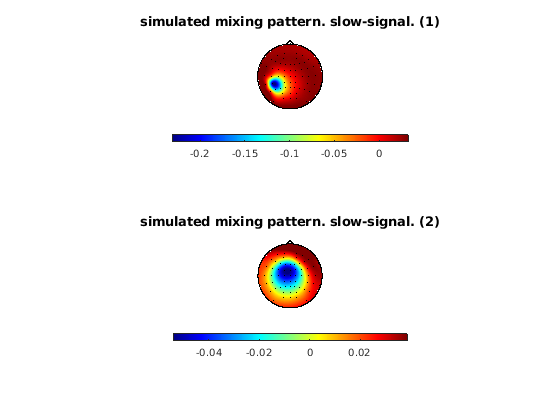

figure, 
subplot(2,1,1)
showfield(pattern_sig_p(:,1), electrode_locs);
title('simulated mixing pattern. slow-signal. (1)')
colorbar('off'), colorbar('southoutside')
set(findall(gca, 'type', 'text'), 'visible', 'on')
subplot(2,1,2)
showfield(pattern_sig_p(:,2), electrode_locs);
title('simulated mixing pattern. slow-signal. (2)')
colorbar('off'), colorbar('southoutside')
set(findall(gca, 'type', 'text'), 'visible', 'on')

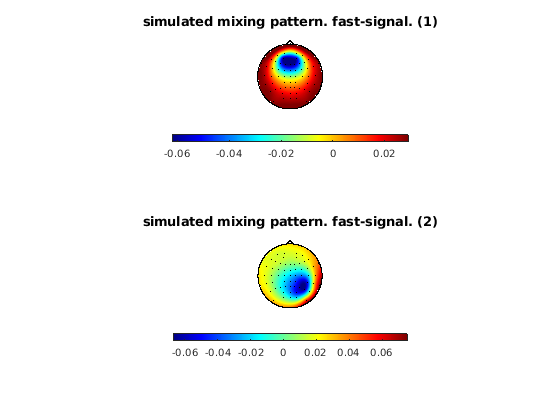


figure, 
subplot(2,1,1)
showfield(pattern_sig_q(:,1), electrode_locs);
title('simulated mixing pattern. fast-signal. (1)')
colorbar('off'), colorbar('southoutside')
set(findall(gca, 'type', 'text'), 'visible', 'on')
subplot(2,1,2)
showfield(pattern_sig_q(:,2), electrode_locs);
title('simulated mixing pattern. fast-signal. (2)')
colorbar('off'), colorbar('southoutside')
set(findall(gca, 'type', 'text'), 'visible', 'on')

## Generating the Source Signals

Now it is the time to generate the source signals in function `mk_elec_CFC`.  In this script, we only bring the phase-coupled option. This is done by producing a base oscilaltion by filtering a white Gaussian noise in the range of the base frequency. Then the slow and fast oscillations are built by multiplying the phase of the base oscillation by the ratios defined at the beigining of the script.

sb = filtfilt(butter_base_b,butter_base_a,randn(T,PairsNum)); 
sp = filtfilt(butter_p_b,butter_p_a,randn(T,PairsNum));  % for using its envelope
sq = filtfilt(butter_q_b,butter_q_a,randn(T,PairsNum)); % for using its envelope
% filter a random white Gaussian noise in the range of FrBase

sb_cplx = hilbert(sb); % analytic signal
sp_abs = abs(hilbert(sp)); % amplitude envelope of a signal at fp
sq_abs = abs(hilbert(sq)); % amplitude envelope of a signal at fq
src_sig_p = real(sp_abs.*exp(1i.*(FrP*angle(sb_cplx)))); 
% build the slow frequency from the base signal, by multiplying its phase 
abs_q = sq_abs;
src_sig_q = real(abs_q.*exp(1i.*(FrQ*angle(sb_cplx) + PhaseLag_q)));

Let's look at the phase-locking value (PLV) of the two sources, their spectrum, and a short segment of their time series:

cPLV = mean(exp(1i*FrQ*angle(hilbert(src_sig_p)))...
    .*exp(-1i*FrP*angle(hilbert(src_sig_q))),1)'

cPLV =    0.9962 - 0.0000i
   0.9967 - 0.0000i


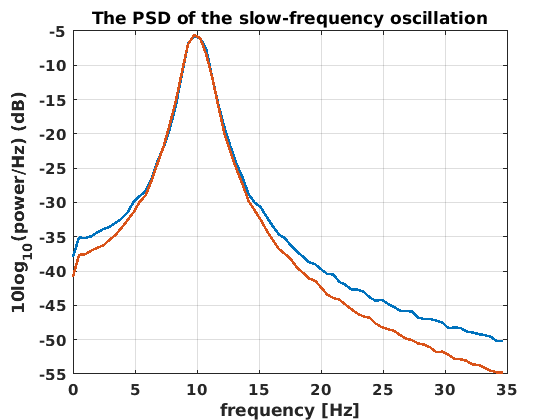


figure,
plot_psd(src_sig_p, Fs, 35);
title('The PSD of the slow-frequency oscillation')
set(gca, 'fontweight', 'bold', 'fontsize', 12)

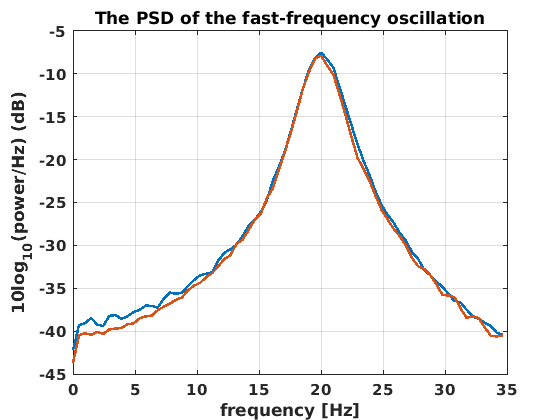

figure,
plot_psd(src_sig_q, Fs, 35);
title('The PSD of the fast-frequency oscillation')
set(gca, 'fontweight', 'bold', 'fontsize', 12)

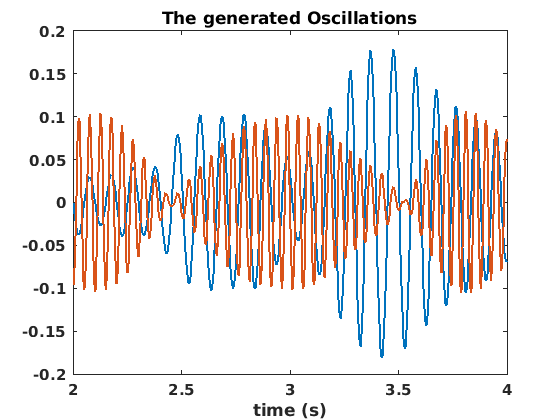


times = (0:T-1)/Fs;
figure,
plot(times(2*Fs:4*Fs), src_sig_p(2*Fs:4*Fs,1), 'linewidth',2), hold on,
plot(times(2*Fs:4*Fs), src_sig_q(2*Fs:4*Fs,1), 'linewidth',2),
xlabel('time (s)')
title('The generated Oscillations')
set(gca, 'fontweight', 'bold', 'fontsize', 12)

Now we generate the noise signals. We also calculate the power of the noise signals in the narrow-bands of the oscillations. We use this powers for adjustment of the SNR in the next step.

src_noise = pinknoise(T,NoiseNum);
elec_noise = src_noise * pattern_noise';

elec_noise_p = filtfilt(butter_p_b,butter_p_a,elec_noise);
elec_noise_q = filtfilt(butter_q_b,butter_q_a,elec_noise);

var_elec_noise_p = sum(var(elec_noise_p));
var_elec_noise_q = sum(var(elec_noise_q));

The adjustment of the SNR is done in the function called `snr_adjust`, where the power of each oscilaltion is adjusted based on the variance of the noise in that bandwidth.

snr_cur = NaN(1,SourceNum);
%% FrP signals
for k = 1:PairsNum
    source = zeros(T,SourceNum);
    source(:,k) = src_sig_p(:,k);
    elec_sig_p = source * pattern_sig';
    var_elec_sig_p = var(elec_sig_p);
    snr_cur(k) = sum(var_elec_sig_p) / var_elec_noise_p;
end
%% FrQ signals
for k = 1:PairsNum
    source = zeros(T,SourceNum);
    source(:,PairsNum+k) = src_sig_q(:,k);
    elec_sig_q = source * pattern_sig';
    var_elec_sig_q = var(elec_sig_q);
    
    snr_cur(PairsNum+k) = sum(var_elec_sig_q) / var_elec_noise_q;
end
%% Normalize SNRs to a given value
src_sig = [src_sig_p src_sig_q];
snr_factor = sqrt(snr_cur / SNR);
src_sig = bsxfun(@rdivide,src_sig,snr_factor);
src_sig_p = src_sig(:,1:PairsNum);
src_sig_q = src_sig(:,PairsNum+1:SourceNum);

## Mixing the Sources

Now that the source signals and their mixing patterns are generated, we can mix them and make the multi-channel signal:

src_sig = [src_sig_p src_sig_q];
elec_sig = src_sig * pattern_sig';

%% Finally, we have signals in the sensors space:
eeg = elec_sig + elec_noise;
% filter between 0.5Hz and 50Hz
[butter_preproc_b, butter_preproc_a] = butter(2,[0.5 50]/(Fs/2));
eeg = filtfilt (butter_preproc_b, butter_preproc_a, eeg);

Now we can look at the PSD of the simulated signal:

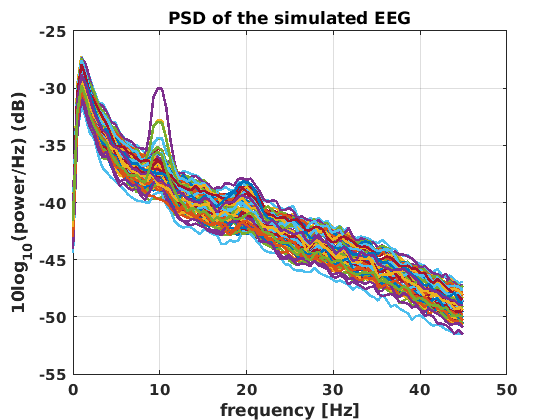

figure,
plot_psd(eeg, Fs, 45);
title('PSD of the simulated EEG')

The 1/f property of the spectrum is due to the pink noise sources. The peaks at alpha and beta bands are the result of the energy of the simulated coupled oscillations. As we see, the peaks are not visible in all the channels, because we simulated only two sources and their activity is not visible in all channels. 

## Functions

function plot_psd(x, fs, max_freq)
% a function to plot the PSD of the input signal
    [pxx,f] = pwelch(x, 2*fs, fs);
    f = f/pi * fs/2;
    pxx = pxx(f<=max_freq, :);
    f = f(f<=max_freq);
    plot(f, 10*log10(pxx), 'linewidth', 2);
    ylabel('10log_{10}(power/Hz) (dB)','fontsize', 12)
    xlabel('frequency [Hz]','fontsize', 12);
    set(gca, 'fontweight', 'bold', 'fontsize', 12)
    grid on,  
end

**Notification: **

THIS SOFTWARE IS PROVIDED BY THE COPYRIGHT HOLDERS AND CONTRIBUTORS "AS IS" AND ANY EXPRESS OR IMPLIED WARRANTIES, INCLUDING, BUT NOT LIMITED TO, THE IMPLIED WARRANTIES OF MERCHANTABILITY AND FITNESS FOR A PARTICULAR PURPOSE ARE DISCLAIMED. IN NO EVENT SHALL THE COPYRIGHT HOLDER OR CONTRIBUTORS BE LIABLE FOR ANY DIRECT, INDIRECT, INCIDENTAL, SPECIAL, EXEMPLARY, OR CONSEQUENTIAL DAMAGES (INCLUDING, BUT NOT LIMITED TO, PROCUREMENT OF SUBSTITUTE GOODS OR SERVICES; LOSS OF USE, DATA, OR PROFITS; OR BUSINESS INTERRUPTION) HOWEVER CAUSED AND ON ANY THEORY OF LIABILITY, WHETHER IN CONTRACT, STRICT LIABILITY, OR TORT (INCLUDING NEGLIGENCE OR OTHERWISE) ARISING IN ANY WAY OUT OF THE USE OF THIS SOFTWARE, EVEN IF ADVISED OF THE POSSIBILITY OF SUCH DAMAGE.